load("PMDdata.mat")


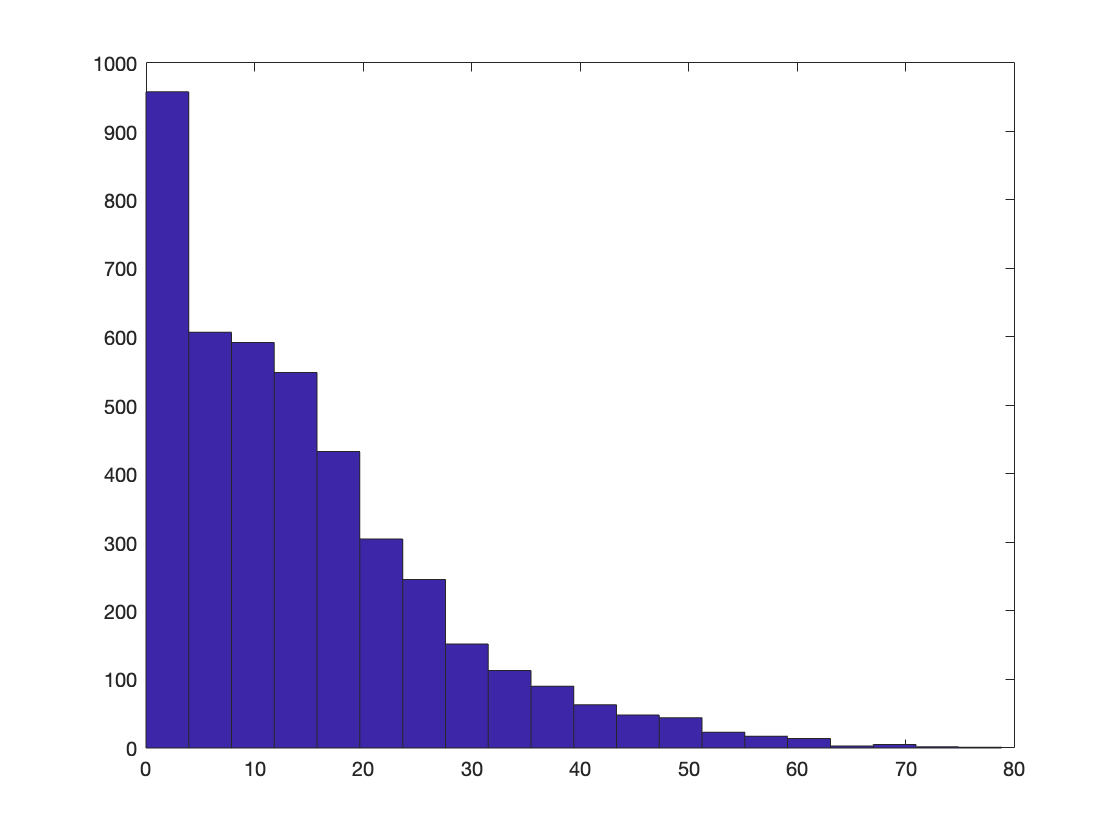

%a)
firingrate = [];
for i = 1:length(PMDdata)
    firingrate(i) = calcfiringrate(PMDdata(i).spikes,500,600);
end
hist(firingrate,20)

%b)
fitFR = fitdist(firingrate', 'Normal')

fitFR =   NormalDistribution

  Normal distribution
       mu =  14.412   [14.0362, 14.7879]
    sigma = 12.5191   [12.2589, 12.7906]


CI = paramci(fitFR)

CI =    14.0362   12.2589
   14.7879   12.7906


CIlow = CI(1,1)

CIlow = 14.0362

CIhigh = CI(2,1)

CIhigh = 14.7879

%confidence interval is between 14.04 to 14.79

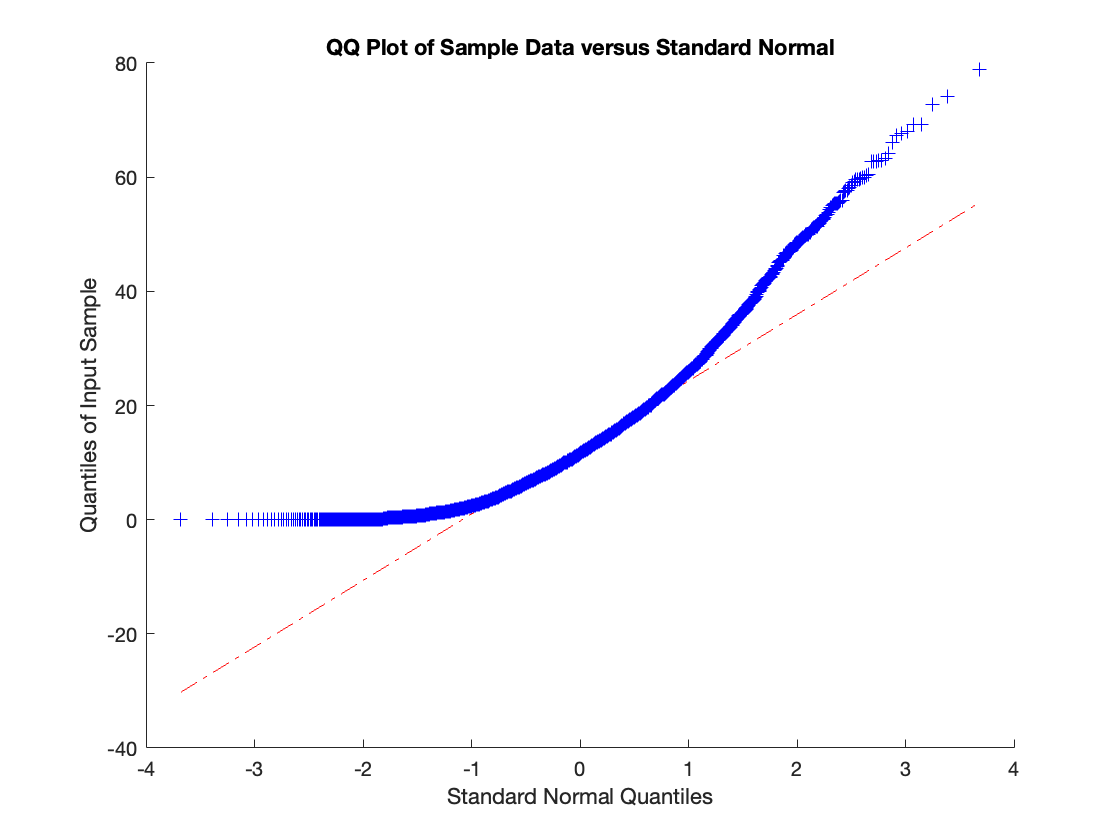

%c)
qqplot(firingrate)

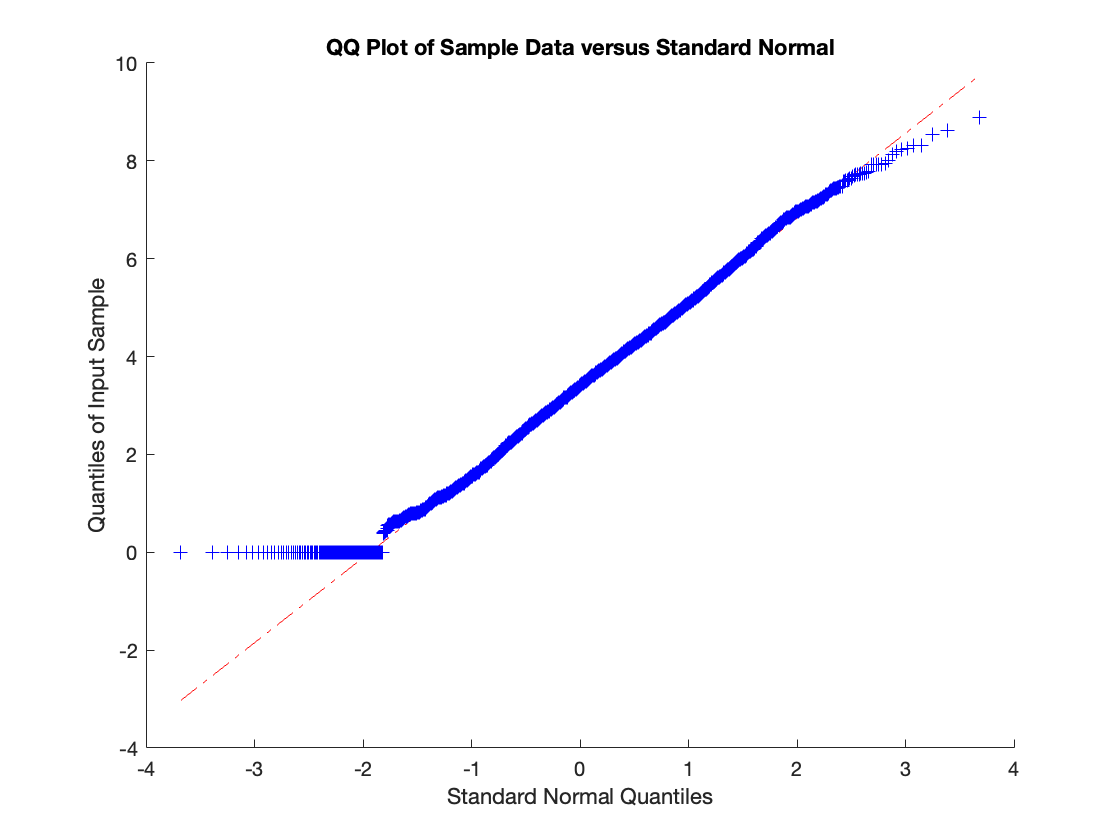

%looks like that square root transformation will make the date more normally
%distributed
Z = sqrt(firingrate);
qqplot(Z)

%d&e) 
bootfun = @(x)(median(x))

bootfun = function_handle with value:
    @(x)(median(x))


[CIboot,STATboot] = bootci(10000,bootfun,firingrate)

CIboot =    11.0714
   12.0185


STATboot =    11.5192
   11.6129
   11.7391
   11.1111
   11.9677
   11.7241
   11.6497
   11.8899
   11.4416
   11.7391


CIbootlow = CIboot(1)

CIbootlow = 11.0714

CIboothigh = CIboot(2)

CIboothigh = 12.0185

%confidence interval is between 11.09 to 12

function FR = calcfiringrate(M,tstart,tend)
S = M(:,tstart:tend);
FR = mean(sum(S,2))/((tend-tstart)/1000);
end

function [FF] = calcfanofac(M,tstart,tend)
S = sum(M(:,tstart:tend),2);
FF = var(S,0,'all')./mean(S,'all');
end